# ACTIVIDAD 1

Nolberto Castro Sánchez A01641501

Liliana Solórzano Pérez A016401392

% %limpiar variables


**Ecuación de la pendiente de Runge Kutta 2**


$$\frac{\mathrm{dy}}{\mathrm{dx}}=\left(y+1\right)\left(x+1\right)\cos \left(x^2 +2x\right),y\left(0\right)=4$$


%%Valores Iniciales
x0 = 0;
y0 = 0;
h = 0.5;
xi = x0:h:2;
yi = zeros(1,length(xi));
yi(1) = 4;

%%Funciónes base
solanali = @(x) 5*exp((1/2)*sin(x^2 + 2*x))-1;
funcion = @(x,y) (y+1)*(x+1)*cos(x^2+2*x);

%%Solución analitica
sol_ana = zeros(1,length(xi));
for i = 1:length(xi)
sol_ana(i) = solanali(xi(i));
end

## Grafiación de los diferentes resultados

hold on
title('Metodos RK2, aproximación')
%Solución Analitica
plot(xi,sol_ana,'-or');
%Metodo de Ralston
y = ralston(xi,yi,h,funcion,solanali);

error_r = 0

error_r = 3.1393

error_r = 36.5313

error_r = 34.7331

plot(xi,y,'-ob');
%Metodo de Heun
yh = heun(xi,yi,h,funcion,solanali);

error_h = 0

error_h = 12.7792

error_h = 40.1546

error_h = 62.9178

plot(xi,yh,'-og');
%Metodo de Punto Medio
ym = medio(xi,yi,h,funcion,solanali);

error_pm = 0

error_pm = 3.8147

error_pm = 20.5578

error_pm = 14.2930

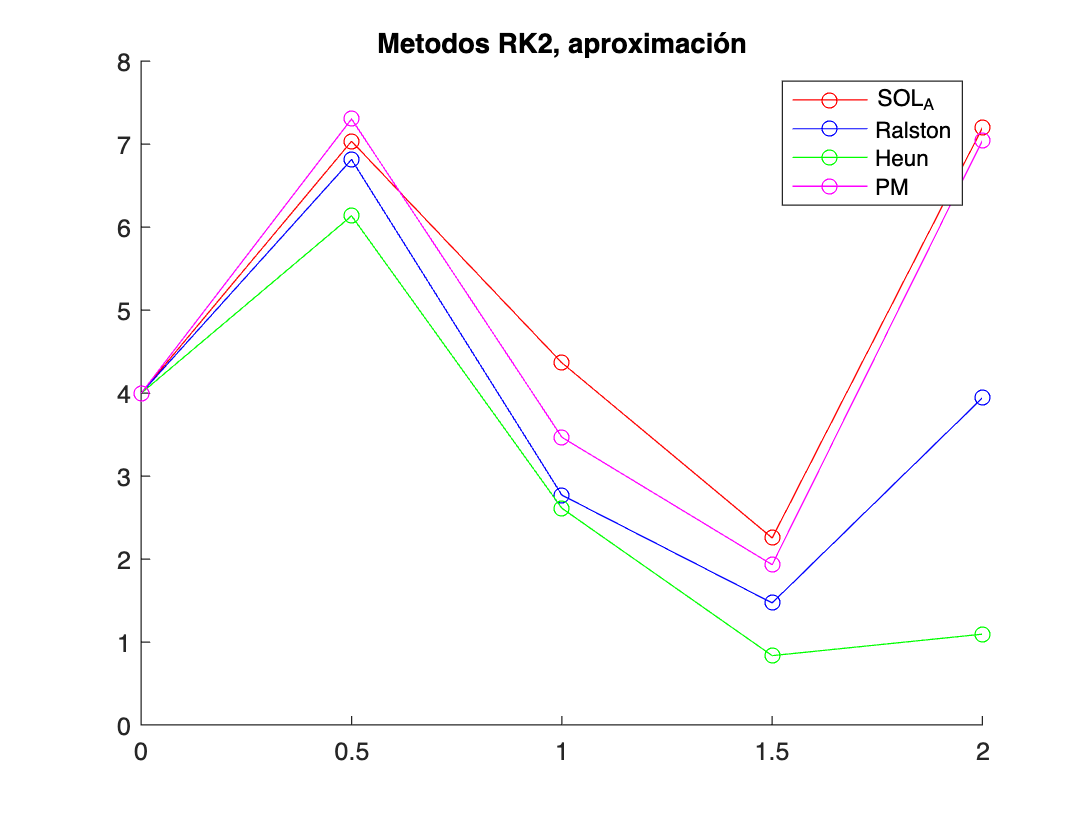

plot(xi,ym,'-om');
legend('SOL_A','Ralston','Heun','PM')
hold off

## Metodo de Ralston

function y = ralston(x,y,h,f,fsolanali)
    ysiguiente = @(y,k1,k2,h) y+((1/3)*k1+(2/3)*k2)*h;
    %%Funciones
    for i = 1:(length(x)-1)
        k1 = f(x(i),y(i));
        xis = x(i) + 0.75*h;
        yis = y(i) + 0.75*k1*h;
        k2 = f(xis,yis);
        y(i+1) = ysiguiente(y(i),k1,k2,h);
        error_r = abs(fsolanali(x(i))-y(i))/fsolanali(x(i))*100
    end
end

## Metodo de Heun

function y = heun(x,y,h,f,fsolanali)
    ysig = @(y,k1,k2,h) y +(((1/2)*k1)+((1/2)*k2))*h;

    %%Funciones
    for i = 1:(length(x)-1)
        k1 = f(x(i),y(i));
        xis = x(i) + h;
        yis = y(i) + (k1*h);
        k2 = f(xis,yis);
        valor_s = ysig(y(i),k1,k2,h);
        y(i+1) = valor_s;
        error_h = abs(fsolanali(x(i))-y(i))/fsolanali(x(i))*100
        
        
    end
        
 end


## Metodo de Punto Medio

 function y = medio(x,y,h,f,fsolanali)
    ysig = @(y,k2,h) y + (k2*h);
    
    %%Funciones
    for i = 1:(length(x)-1)
        k1 = f(x(i),y(i));
        xis = x(i) + 0.5*h;
        yis = y(i) + k1*(h/2);
        k2 = f(xis,yis);
        valor_s = ysig(y(i),k2,h);
        y(i+1) = valor_s;
        error_pm = abs(fsolanali(x(i))-y(i))/fsolanali(x(i))*100
    end
end